%% WV Eddy
%alongtrackLonLat from OceanDB
%eddyPath_track from ssh max closed contour centroid
%eddy_field is an array of eddy field in (x,y,t,ssh)
clear all

## 1. Extract tracks along the eddy path

% define domain
readdir = 'G:\My Drive\AlongTrack\';
filename = 'BetaEddyOne.nc';
% Load Model
x_QG = ncread([readdir, filename], 'x'); %meters
y_QG = ncread([readdir, filename], 'y'); %meters
ssh = squeeze(ncread([readdir, filename], 'ssh')); %meter;% matrix order in x,y,z

totalDays = size(ssh, 3);
x = x_QG - mean(x_QG);
y = y_QG - mean(y_QG);

eddy_field.x = x;
eddy_field.y = y;
eddy_field.t = [1:totalDays];
eddy_field.ssh = ssh;

%find eddy center
[center_xoyo,amplitude,radius,core_xy] = findEddyCentroid(x, y, ssh,'thresholdratio',0.9,'GetBoundary', true);
eddyPath.xe = center_xoyo(:,1);
eddyPath.ye = center_xoyo(:,2);

%if you want to change the eddyPath to a function handle
eddyPath_fun_t.xe = @(t) interp1(eddy_field.t, eddyPath.xe, t, 'linear', 'extrap');
eddyPath_fun_t.ye = @(t) interp1(eddy_field.t, eddyPath.ye, t, 'linear', 'extrap');

% % extract track - takes somes time bc it loads the entire track matrix
% my_readdir = 'G:\My Drive\AlongTrack\';
% alongtrackLatLon = alongtrackFromXYDomain(x,y,totalDays,lono=-40,readdir=my_readdir); %options: lato=24, lono=305

current_file_path = matlab.desktop.editor.getActiveFilename;
[current_dir, ~, ~] = fileparts(current_file_path);
% save(strcat(current_dir,'\alongtrackLatLon_QG.mat'),'alongtrackLatLon')

load(strcat(current_dir,'\alongtrackLatLon_QG.mat'))

alongtrackXY = latlon2xy_centered(alongtrackLatLon);

## 2. Apply OSSE on your choice of an analytical eddy shape

%Output: alongtrack - contains arrays of lon,lat,x,y,t,ssh of OSSE 
% apply OSSE on an eddy_field from QG model in (x,y,t)
alongtrack = subsampleOSSE(alongtrackXY,eddy_field);


## 3. Plots and Videos of OSSE

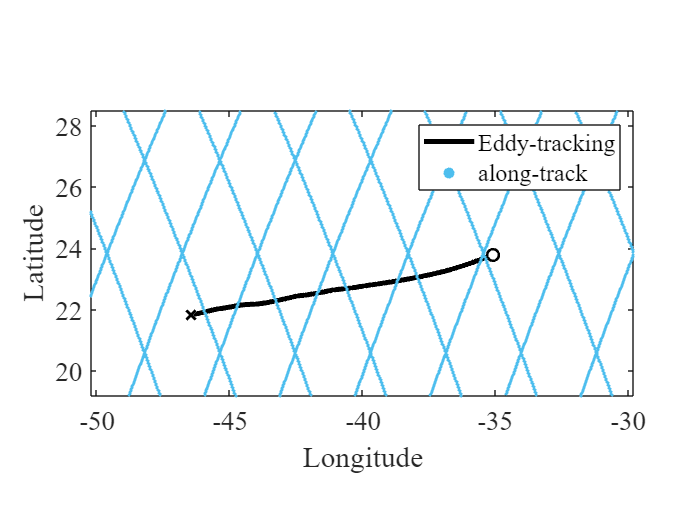

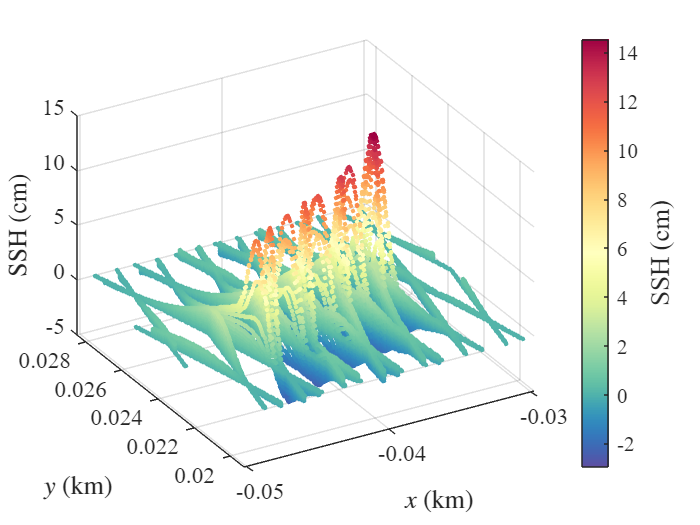

%% plot eddy path with alongtrack, and OSSE
alongtrackLatLon.ssh=alongtrack.ssh; %plotAlongtrack takes in lat lon info
plotAlongtrack(alongtrackLatLon,eddyPath);

%% make video of the propagating eddy
video_name = 'eddy_field_QGmodel';
makePropagatingVideo(x,y,totalDays,eddy_field,video_name)


## 4. Eddy composites and plots from full field

% eddy center from eddyPath
% Full field struct
[X,Y,T] = ndgrid(1:length(x), 1:length(y), 1:totalDays);
fullfield.x = x(reshape(X,[],1));
fullfield.y = y(reshape(Y,[],1));
fullfield.t = reshape(T,[],1) - 1; % Subtract 1 to match your indexing
fullfield.ssh = reshape(ssh,[],1);

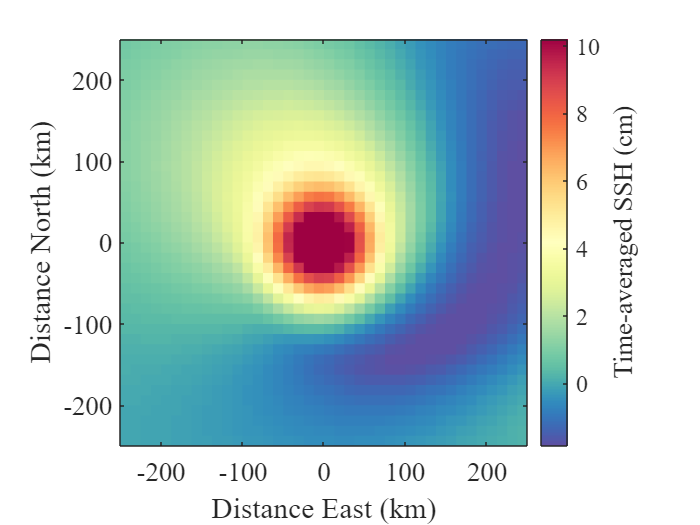

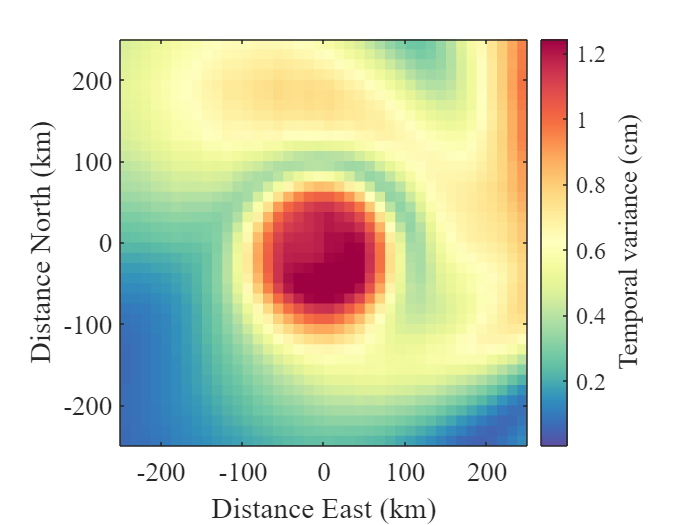

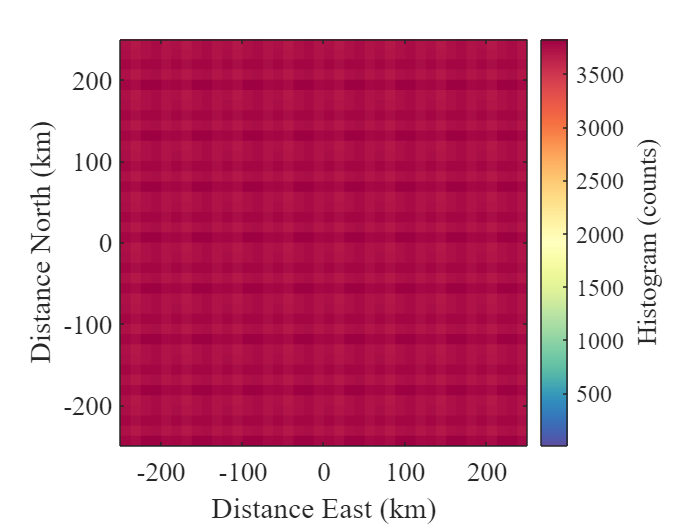

% time-averaged eddy composite from full field
[mz_xy, xmid_xy, ymid_xy, numz_xy, stdz_xy] = composite2D(fullfield,eddyPath_fun_t);% options: bin_size=12.5*1e3

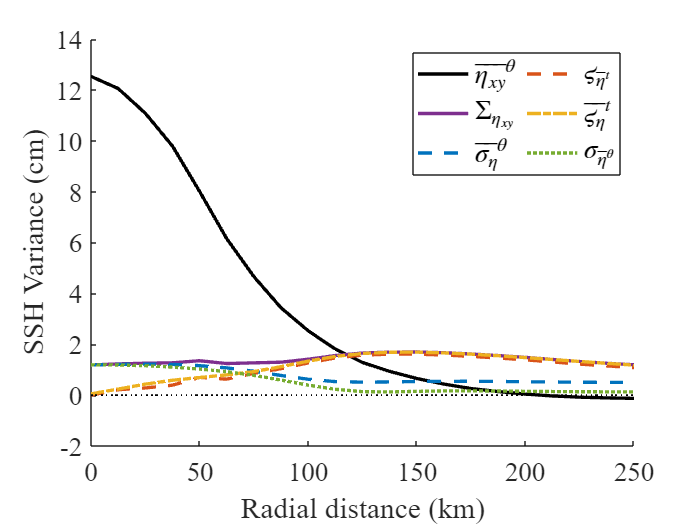

% time-averaged radial profile
[mz_r, rmid_r, numz_r, stdz_r] = radialProfile(fullfield,eddyPath_fun_t);

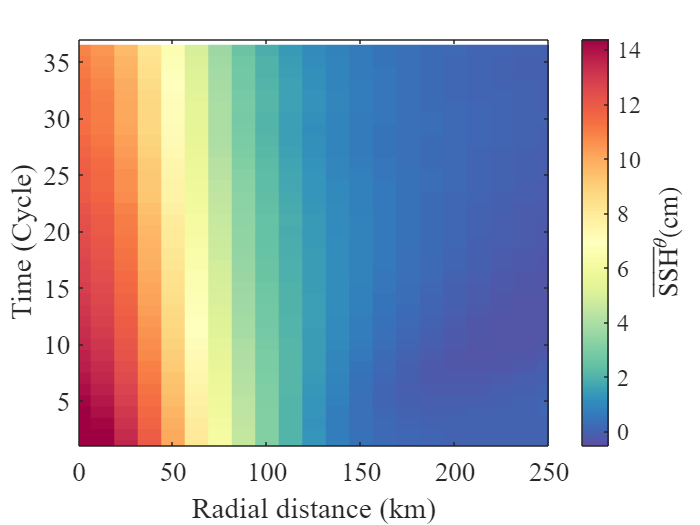

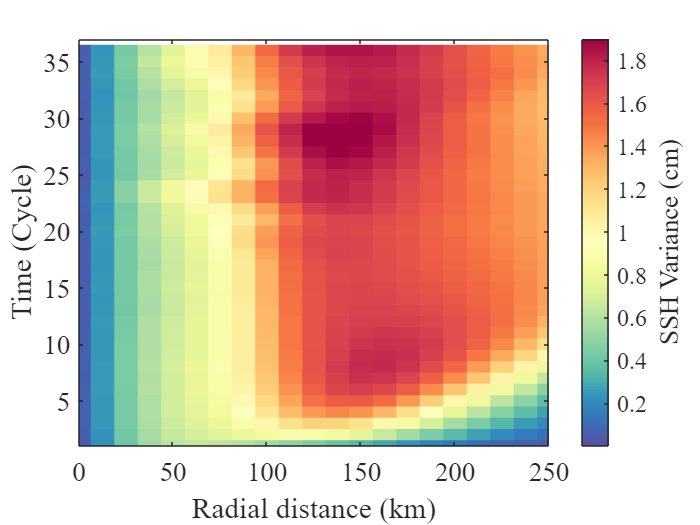

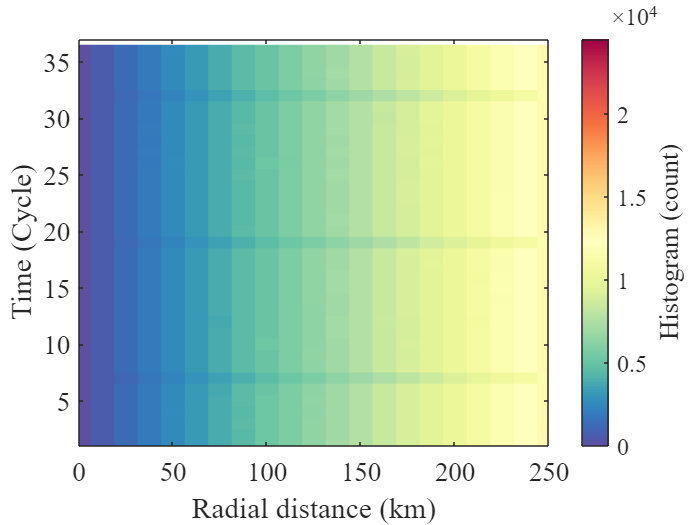

% radialProfile over time
[mz_rt, rmid_rt, tmid_rt, numz_rt, stdz_rt] = radialProfileTime(fullfield,eddyPath_fun_t);

## 4. Eddy composites

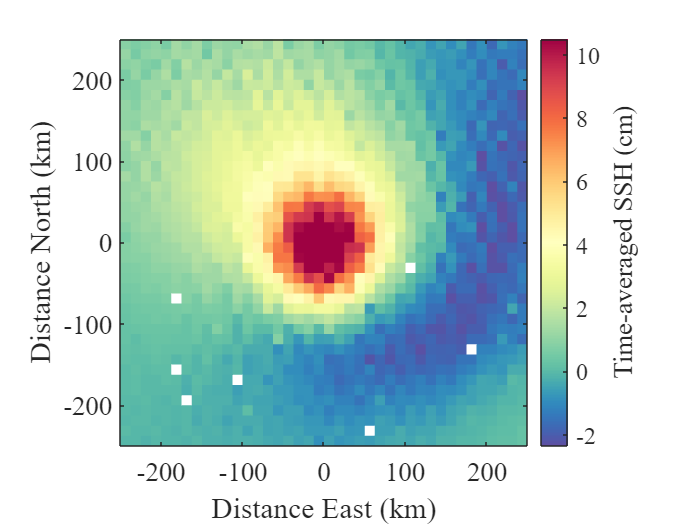

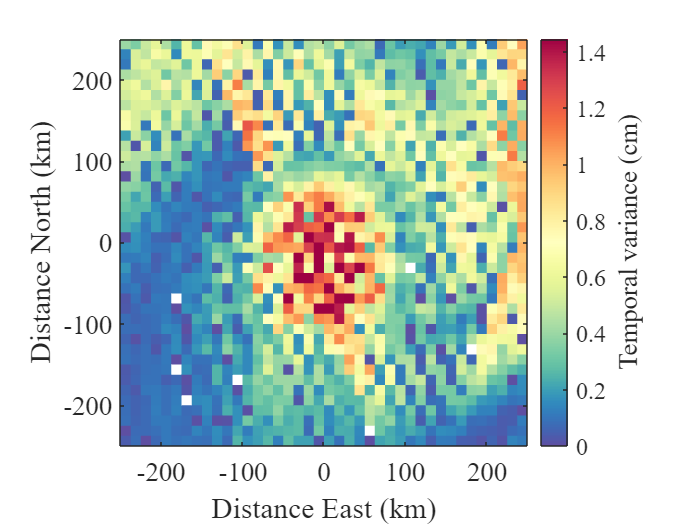

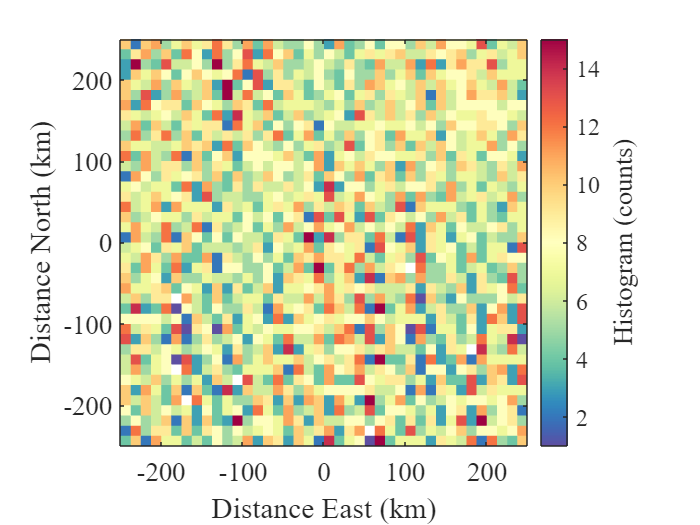

%eddy center from eddyPath_track, which is from ssh max closed contour centroid
% time-averaged eddy composite
[mz_xy, xmid_xy, ymid_xy, numz_xy, stdz_xy] = composite2D(alongtrack,eddyPath_fun_t);% options: bin_size=12.5*1e3

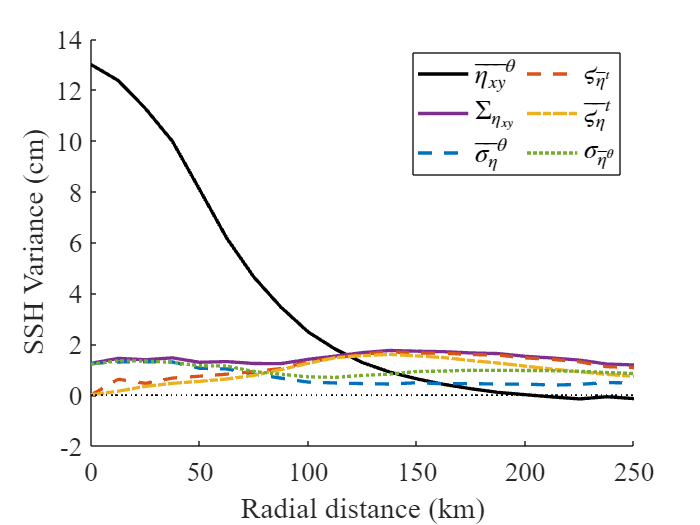

% time-averaged radial profile
[mz_r, rmid_r, numz_r, stdz_r] = radialProfile(alongtrack,eddyPath_fun_t);

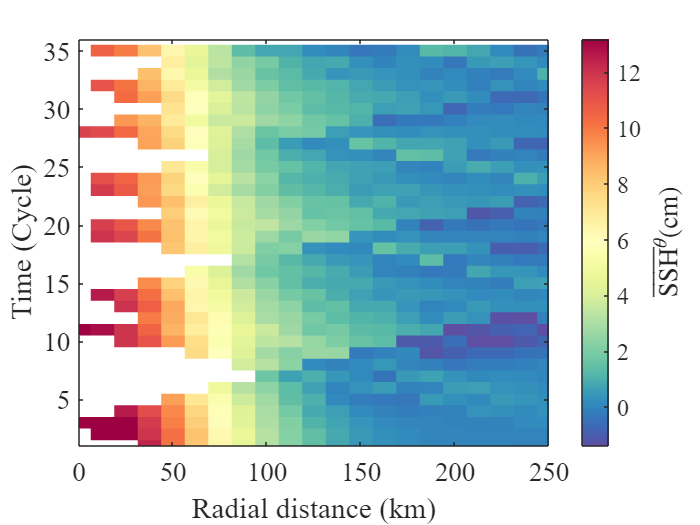

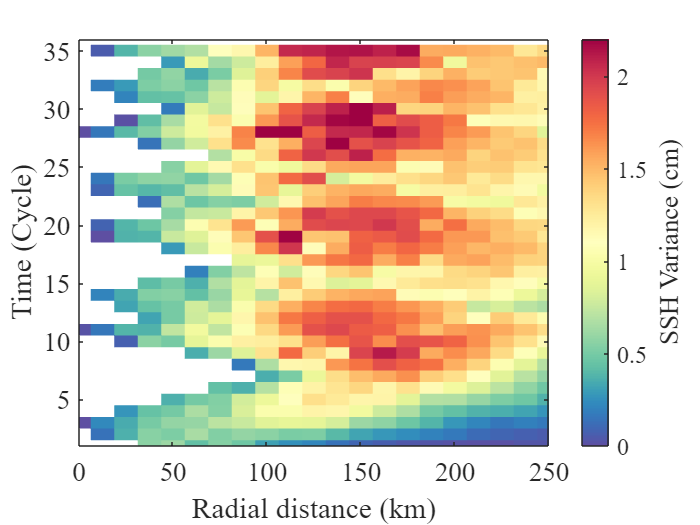

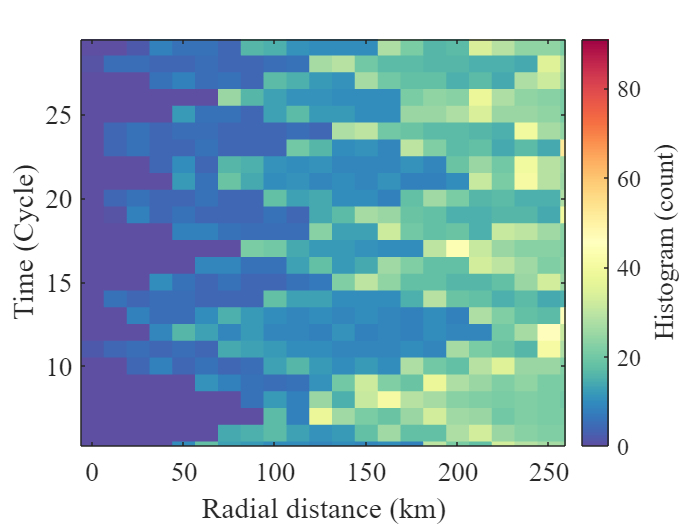

% radialProfile over time
[mz_rt, rmid_rt, tmid_rt, numz_rt, stdz_rt] = radialProfileTime(alongtrack,eddyPath_fun_t);

## Relative vorticity and Streamfunction

fullfield2D.x = x;
fullfield2D.y = y;
fullfield2D.t = [1:totalDays]-1;
fullfield2D.ssh = ssh;
[zeta] = zetaField(fullfield2D,eddyPath_fun_t);
[center_zeta,~,~,core_zeta,shield_zeta] = findEddyCentroid(x, y, ssh,'BoundaryType','zero-zeta','GetBoundary', true,'epsilon',0.1);
% add an elipse fit to the shield

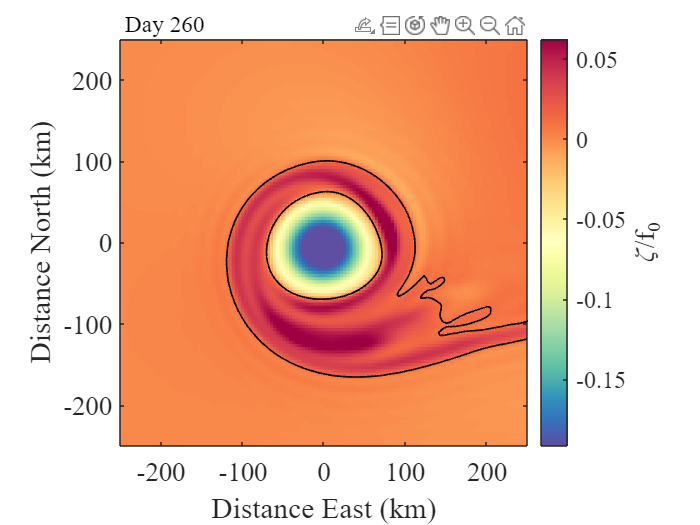

n=260;
zetaContours.core=core_zeta{n};
zetaContours.shield=shield_zeta{n};
plotComposite(fullfield2D.x,fullfield2D.y,fullfield2D.t(n) - min(fullfield2D.t),zeta(:,:,n),eddyPath_fun_t,contour=zetaContours)
hold on
text(-245,270,['Day ',num2str(n)],'FontSize',14,'FontName','times')

%%
[mz_zeta, rmid] = zetaProfile(fullfield2D,eddyPath_fun_t);
% streamfunction, energy, enstrophy
% psi=@(x,y,t) (g/fo)*eddy_model
% syms x y t
% u_sym=-diff(psi,y);
% v_sym=diff(psi,x);
% u=@(x,y,t) u_sym;

## Test parameters extraction

%% 
% replace center_xy with centroid of 90% max ssh
% [center_xoyo,amplitude,radius,core_xy] = findEddyCentroid(x, y, ssh,'thresholdratio',0.9,'GetBoundary', true);
plotParameters(alongtrack)


## 5. Convergence Rate

% how many cycles are needed to reach convergence to time-averaged profile
[convergence] = convergenceRate(mz_rt, numz_rt);


## 6. Gaussian fit

eddyFit_fun = @(x,y,t,A,L,x0,y0,cx,cy) A.*exp(-((x-x0-cx*t).^2 + (y-y0-cy*t).^2)/L^2);
true_params.A = params.A;
true_params.L = L;
true_params.x0 = x0;
true_params.y0 = y0;
true_params.cx = vx;
true_params.cy = vy;

initParams.A = true_params.A-0.02;
initParams.L = true_params.L+5e3;
initParams.x0 = true_params.x0-50e3;
initParams.y0 = true_params.y0+50e3;
initParams.cx = true_params.cx-0.2e3;
initParams.cy = true_params.cy+0.2e3;

plot_func = @(xtrans, optimValues, state) plotParamsIteration_ref(xtrans, optimValues, state, [], true_params);
it_options = optimset('OutputFcn', plot_func,'TolX',1e-3,'TolFun',1e-3);
paramsFit = FitAlongTrackXYToEddyModel(alongtrack, eddyFit_fun, initParams, it_options);
plotFitPosition(paramsFit,true_params)
xlim([min(x),max(x)]);ylim([min(y),max(y)])

%% time windowed fit
it_options = optimset('TolX',1e-3,'TolFun',1e-3);
[paramsCell, initParamsCell] = FitAlongTrackXYToEddyModelWindowed(alongtrack, eddyFit_fun, initParams, eddyPath_fun_t, it_options);
plotFitPosition(paramsCell,initParamsCell)
xlim([min(x),max(x)]);ylim([min(y),max(y)])
plotFitWindowed(paramsCell,true_params, eddyPath_fun_t)
